# Imports

% for stimulator
folder = 'NewBoardTest';
addpath(genpath(folder));

% 
ComPort        = 'COM28';
Baudrate       = 115200*8;   %921600
 
run('OpenComPort.m'); %
clc;

addpath(genpath('MEP_Detection'));  %to have the MEP functions
addpath(genpath('LINK')); %to have the Matlab-DataLink connection functions

% Specify the folder path to save the data
folderPath = 'DATA/Kelly'; % change this according to recording subject

% Check if the folder exists, if not, create it
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

# Protocol

*follow*[* these steps *](matlab:open('./matlab_DL_link.pdf'))*for connecting Matlab to Biometrics Datalink*

- Launch the Biometrics Datalink

- The Biometrics Application MUST have file save mode turned off

- Run [DatalogInit.m](matlab:open('..\MATLAB\DataLogInit.m')) 

%DataLogInit

        4. Setup a sensor and record it in the Biometrics Application

        5. Select Channel and set parameters

        6. Run [getDataFromChannel.m](matlab:open('./getDataFromChannel.m')) to extract real time data

%getDataFromChannel(channel,sampleRate,numberOfValues);

         7. Run MEP detection to detect MEP in real time by using functions in the MEP folder

### **IMPORTANT : The Data can only be acquired for 50000 samples (50s if 1000 sf) before the data overflows. After 50s STOP and START the EMG recording.**

Remarks : 

- You cannot send twice the same samples so NO OVERLAPPING WINDOWS. Practically this means if you take windows of 2s, when you press the first time 'getDataFromChannel' you will get the 2s window. However if you press a second time on 'getDataFromChannel' before waiting 2s, you will only get the remaining. Example: for a 2s window, sending data request 1.5s after the first request will only give you a 1.5s window since 0.5s overlap with the previous window.

- In the same lines, if your window is bigger than the elapsed time from the start of the recording you will only get the available samples. Example : for a 2s window, press START at t = 0, sending data request after 1s will only get you a 1s window.

- The EMG seems to take windows following each other even if we are far in time : if you take a 5s window at time 10s it will take window 0-5s not 5-10s so if you need to do pauses make sure you get the data of the pause before getting data of interest.

# Set Parameters

With the following parameters we have a first pulse of 10ms, interpulse interval of 50ms, interframe interval of 5s.

selectedChannels = {0,1,2,3,4,5}; % channel to record from, multiple channels will be used later. Channel 0 here is channel 1 on BIOMETRICS
muscleLocations = {'distal','distal','distal','distal','proximal','proximal'}; % for each channel put the corresponding distal or proximal
updateRate = 0.01; %in s
sf = 1000; %sampling frequency of channel acquisition
%numberOfValues = 680; %windows of 680ms (-30ms before, +650ms after first stimulus)


        2000



values_before_stim = 1000; %100ms before the stimulation
values_after_stim = 1000; %1s after the stimulation
numberOfValues = values_before_stim+values_after_stim; 
disp(numberOfValues);


% EMG preprocessing
plot_chs = false;
bool_plot_PSD = false;
selected_filters = 3;
paper_nb = 1;



SetSingleChanState(s, 0, 1, 1, 0); %should turn red
%SetSingleChanState(s, 1, 1, 1, 0);


% Stimulation Variables
pulse_width = uint32(490); % us --- Fixed --- Remember this is half of the duration of a bi-phasic pulse
pulse_width_1pulse = uint32(1000); % us --- Fixed --- The total duration of a burster (made of several short bi-phasic pulses)
N_pulse_repetition = 2;     % --- Insert 1 to Single Pulse (SP)-  2 to Double Pulse (DP) --- the number of inner bi-phasic pulses in a burster.   
interpulse_duration = uint32(50 *1000); % us - ms --- for Double pulse. Usually between 35-100ms --- time between two bi-phasic pulses. 
pulse_deadtime = uint32(20);        % us - --- Fixed ---  20 is the minimum
interframe_duration = uint32( 5000000 ); % us - s 
%burst_interframe_duration = uint32( 1e6 * 1/STIMULATION_FREQ - ...    % --- Not used for PRM reflex --- 
%                                       (burst_inner_pulse_repetition * (2 * burst_single_phase_pulse_duration + burst_pulse_deadtime) ) ... % the total duration of the bi-phasic pulses including deadtime
%                                       ) ; % us. This is the time between two bursters. - Not necessary for SP and DP
current =  15; % mA
max_current = 10; % mA

% MEP detection
bool_plot_MEP = false;
bool_colour_response = false;

# Prepare Stimulator parameters

SetSingleChanAllParam_v2(s, 0, ...
                        pulse_width, ...    % pulseDurationUS
                        pulse_deadtime, ...                 % deadTimeUS
                        interpulse_duration, ...            % interpulseDurationUS
                        interframe_duration, ...            % interframeDurationUS
                        N_pulse_repetition, ...         % numberOfPulsesPerFrame
                        current,...               % IAmplitude in mA
                        0);

%% Enable Trigger Mode
SetSingleChanSingleParam_v2(s, 0, 7, 0) % Trigger mode (7), Output
SetSingleChanState(s, 0, 1, 0, 0) %  Output disabled

# Real time MEP detection

In this part we aim to detect in real time the Muscle Evoked Potentials at each stimulation. To do so, we perform 3 repetitions at each current value, increasing the current by steps of 5mA. We collect the data, preprocess it and analyze the response.

%% Enable Trigger Mode
SetSingleChanSingleParam_v2(s, 0, 7, 0) % Trigger mode (7), Output
SetSingleChanState(s, 0, 1, 0, 0) %  Output disabled 


current = 20;

SetSingleChanAllParam_v2(s, 0, ...
                        pulse_width, ...    % pulseDurationUS
                        pulse_deadtime, ...                 % deadTimeUS
                        interpulse_duration, ...            % interpulseDurationUS
                        interframe_duration, ...            % interframeDurationUS
                        N_pulse_repetition, ...         % numberOfPulsesPerFrame
                        current,...               % IAmplitude in mA
                        0);

SetSingleChanState(s, 0, 1, 1, 1);

SetSingleChanSingleParam_v2(s, 0, 9, 1);

% for now only one channel is being taken real time and the others are
% saved for offline analysis.

%params to tune each time : current_0 and real_time_channel
% can also tune pause(0.920) updated t_0 for synchronization if they change

folderPath = 'DATA/Kelly/small_electrode/yellow3_ipsilateral/real_time_channel2';
% Check if the folder exists, if not, create it

if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

current_0 = 40; %set the current to start the loop with.
real_time_channel = selectedChannels{1}; % set the real time channel

EMG_data = [];

numberOfrepetitions = 3; %i value
numberOfcurrents = 2; %j value
all_responses = cell(numberOfcurrents, numberOfrepetitions); % jxi array of responses
all_amplitudes = cell(numberOfcurrents, numberOfrepetitions); % jxi array of amplitudes of first MEP

current_initial = 15; % small comfortable current to only see artifact
SetSingleChanSingleParam(s, 0, 6, current_initial);

SetSingleChanState(s, 0, 1, 1, 0); % activate High Voltage
pause(2)
SetSingleChanState(s, 0, 1, 1, 1); % activate output

start_time = tic;

emg_removed = getDataFromChannel(real_time_channel,sf,40000); % remove available samples before recording

t_0 = 1000; % we record windows starting 1s before stimulation (see pause(0.920) line  112)

getData returned 0 from channel 1


Repetition: 1


Current: 50


Getting current at time : 5.9398


Looking at pulse at time t_0 = : 960


INTERPULSE FIRST
   50

    2.1707

PEAKS
     2     1

lOCS
   325
   376

ok1
ok2


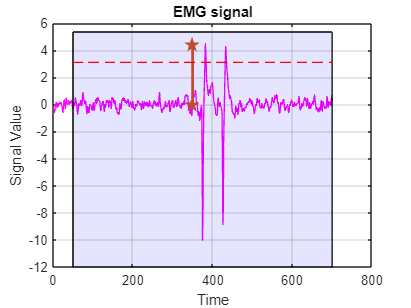

Response for current 50 and repetition 1: presumed M-wave


Processing time: 0.0658 seconds


Repetition: 2


Current: 50


Getting current at time : 11.0206


Looking at pulse at time t_0 = : 920


INTERPULSE FIRST
   50

    1.6534

PEAKS
     2     1

lOCS
   363
   414

ok1
ok2


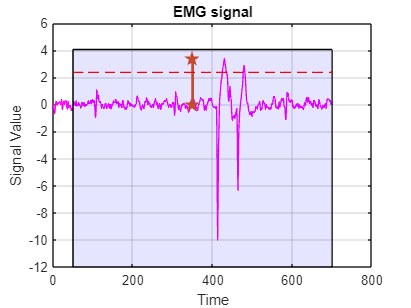

Response for current 50 and repetition 2: presumed M-wave


Processing time: 0.0622 seconds


Repetition: 3


Current: 50


Getting current at time : 16.0862


Looking at pulse at time t_0 = : 880


INTERPULSE FIRST
   50

    1.9090

PEAKS
     2     1

lOCS
   400
   451

ok1
ok2


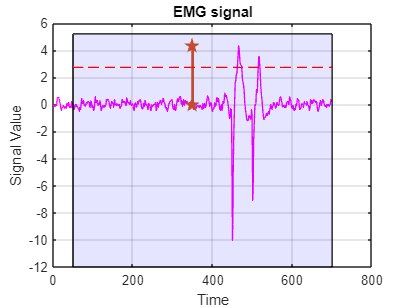

Response for current 50 and repetition 3: presumed M-wave


Processing time: 0.0653 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Repetition: 1


Current: 55


Getting current at time : 21.1586


Looking at pulse at time t_0 = : 960


INTERPULSE FIRST
   50

    1.7518

PEAKS
     2     1

lOCS
   318
   369

ok1
ok2


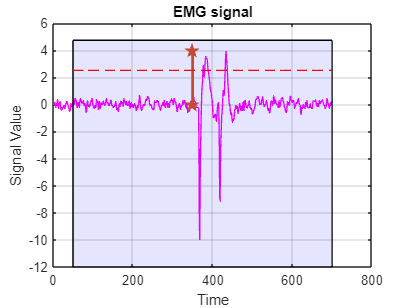

Response for current 55 and repetition 1: presumed M-wave


Processing time: 0.0645 seconds


Repetition: 2


Current: 55


Getting current at time : 26.2248


Looking at pulse at time t_0 = : 920


INTERPULSE FIRST
   50

    0.4938

PEAKS
     4     1

lOCS
   355
   379
   406
   438

ok1
not ok 2


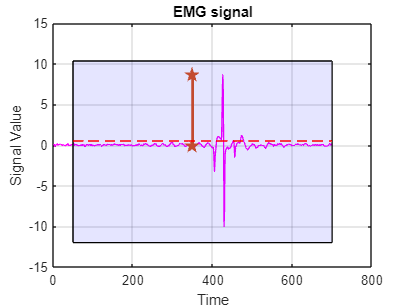

Response for current 55 and repetition 2: no or invalid response


Processing time: 0.0698 seconds


Repetition: 3


Current: 55


Getting current at time : 31.3056


Looking at pulse at time t_0 = : 880


INTERPULSE FIRST
   50

    0.5602

PEAKS
     4     1

lOCS
   392
   417
   443
   477

ok1
not ok 2


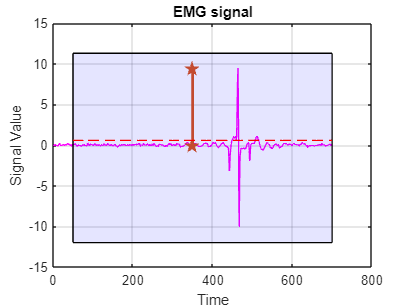

Response for current 55 and repetition 3: no or invalid response


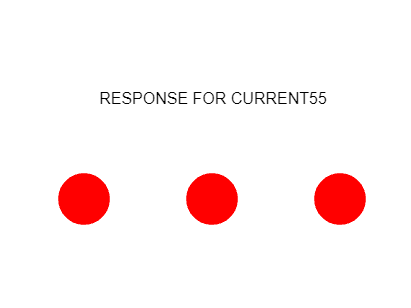

Processing time: 0.0677 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


theoretical_elapsed_time = 0;
offset = 0;

emg_removed = getDataFromChannel(real_time_channel,sf,40000); % remove available samples before recording

SetSingleChanSingleParam(s, 0, 6, current_0)

pause(0.920); % pause accounts for delay when sending the next command SetSingleChanSingleParam_v2(s, 0, 9, 1). Based on tests.

SetSingleChanSingleParam_v2(s, 0, 9, 1);


for j = 1: numberOfcurrents    % Need to be increased
    current =  current_0 + (j-1)*5; % mA, it will start the first 3 repetitions at current_0
    SetSingleChanSingleParam(s, 0, 6, current)
    

    for i = 1: numberOfrepetitions  % Number of repetitions

        % Enable Output
        pause(5)
        numberOfValues = 5000;
        %collect EMG data and process it
        for_timer = tic; % start timer
        theoretical_elapsed_time = theoretical_elapsed_time+5;
        offset = offset+ toc(start_time)-theoretical_elapsed_time;
        
        % CHANGE OFFSET DAILY BASED ON OFFSET TESTS. EITHER -50 , 0 , +50
        
        %updated_t_0 = t_0 +offset+49*i; %offset is computation time and 49(ms) is the time shift of each window
        updated_t_0 = t_0-40*i; %offset is computation time and 49(ms) is the time shift of each window

        disp(['Repetition: ', num2str(i)]);
        disp(['Current: ', num2str(current)]);
        emg_data = getDataFromChannel(real_time_channel,sf,numberOfValues); % collect data
        disp(['Getting current at time : ', num2str(toc(start_time))]);



        [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_data))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
        
        % emg_for_training=emg_data(1,2000:end);
        % ACSR_window=200;
        % emg_filtered=ACSR_filter(emg_for_training,emg_data,ACSR_window);
        % norm_factor_afterfilter = 1;

        EMG_data =[EMG_data;double(emg_data)'];

        bool_plot_MEP = true;
        bool_colour_response =true;
        % APD SHOULD ONLY TAKE 1 channel!! TO BE CHANGED 
        disp(['Looking at pulse at time t_0 = : ', num2str(updated_t_0)]);
        
        %response = ActionPotDetectDoublePulse3(updated_t_0,muscleLocations{1},double(emg_data)',sf,interpulse_duration/1000,norm_factor_afterfilter,bool_plot_MEP,bool_colour_response,numberOfValues); %find response with raw data
        [response,p2p_amplitude] = ActionPotDetectDoublePulse3(updated_t_0,EMG_preprocessed, interpulse_duration/1000,norm_factor_afterfilter,bool_plot_MEP,numberOfValues); %find response 'no response', 'MEP reflex', 'M-wave', 'invalid'
        
        all_responses{j, i} = response;  
        all_amplitudes{j, i} = p2p_amplitude;  

        fprintf('Response for current %d and repetition %d: %s\n', current, i, response);
        plot_response(all_responses(j, :),current);
        % Save the data in the 'DATA' folder
        filename = fullfile(folderPath, sprintf('emg_current%d_repetition%d_window%ss_interpulse%s.mat', current,i,num2str(numberOfValues/sf),num2str(interpulse_duration/1000)));
        save(filename, 'emg_data'); % saving raw data

        elapsed_time_loop = toc(for_timer); % stop timer
        fprintf('Processing time: %.4f seconds\n', elapsed_time_loop);

        
    end

    disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

Getting last current at time : 31.3746


    
    
end
disp(['Getting last current at time : ', num2str(toc(start_time))]);
% %Soleus_R in real time

currentString = generateCurrentString(current_0, numberOfCurrents);


emg_data = getDataFromChannel(selectedChannels{2},sf,45000); % collect data Soleus_L
filename = fullfile(folderPath, ['full_emg_SO_R_', currentString, '.mat']);

save(filename, 'emg_data'); % saving raw data

emg_data = getDataFromChannel(selectedChannels{3},sf,45000); % collect data TA_R
filename = fullfile(folderPath, ['full_emg_TA_R_', currentString, '.mat']);
save(filename, 'emg_data'); % saving raw data

emg_data = getDataFromChannel(selectedChannels{4},sf,45000); % collect data TA_L
filename = fullfile(folderPath, ['full_emg_TA_L_', currentString, '.mat']);
save(filename, 'emg_data'); % saving raw data

emg_data = getDataFromChannel(selectedChannels{5},sf,45000); % collect data RF_R

getData returned 0 from channel 4


filename = fullfile(folderPath, ['full_emg_RF_R_', currentString, '.mat']);
save(filename, 'emg_data'); % saving raw data

emg_data = getDataFromChannel(selectedChannels{5},sf,45000); % collect data RF_L
filename = fullfile(folderPath, ['full_emg_RF_L_', currentString, '.mat']);
save(filename, 'emg_data'); % saving raw data

SetSingleChanState(s, 0, 1, 0, 0);

## OLD VERSIONS (with manual synch)

% VERSION 1
EMG_stim =[];
EMG_data = [];
EMG_trigger = [];
SetSingleChanState(s, 0, 1, 1, 1);

start_time = tic;


% The following section aims to find the T_0
current = 15; % small comfortable current to only see artifact
not_found = true;
SetSingleChanSingleParam(s, 0, 6, current)

while not_found
    pause(4);
    loop_time = tic;
    emg_stim = getDataFromChannel(selectedChannels{1},sf,4000); % collect data    
    
    [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_stim))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
    [not_found, time] = StimPulseDetection(EMG_preprocessed,interpulse_duration,sf);
    EMG_stim =[EMG_stim;double(emg_stim)'];
    elapsed_time = toc(loop_time);
end

time_step_1 = toc(start_time);
disp("FOUND after :");
disp(time_step_1);

disp("waiting for :");
disp(time-elapsed_time);
disp("elapsed_time from loop");
disp(elapsed_time);
pause(time-elapsed_time);

disp("taking interval emg at time : ");
disp(toc(start_time));

emg_interval= getDataFromChannel(selectedChannels{1},sf,15000); % collect data a enlever pour apres
[not_found, time] = StimPulseDetection((double(emg_interval))',interpulse_duration,sf);
n_samples = length(emg_interval(1,:));
disp("extra time :")
disp(n_samples-(n_samples - (5 * sf - time * sf)));


disp("STARTING CURRENT LOOP at time : ");
disp(toc(start_time));

for j = 1: 1    % Need to be increase if 
    current =  30 + j*5; % mA 
    SetSingleChanSingleParam(s, 0, 6, current)
    
    for i = 1: 3  % Number of repetitions
        % Enable Output
        %pause(values_after_stim/sf) %A RECHANGER A 650 take window of 680ms after 650ms of stimulation (it will take 650ms for the first run since we won't have 680 available values)
        pause(4)
        numberOfValues = 5000;
        % collect EMG data and process it
        tic; % start timer
        
        disp(['Repetition: ', num2str(i)]);
        disp(['Current: ', num2str(current)]);
        emg_data = getDataFromChannel(selectedChannels{1},sf,numberOfValues); % collect data
        emg_trigger= getDataFromChannel(8,sf,numberOfValues); % collect data        

        [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_data))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
        
        EMG_data =[EMG_data;double(emg_data)'];
        %EMG_trigger = [EMG_trigger;emg_trigger];

        response = ActionPotDetectDoublePulse(muscleLocations{1},EMG_preprocessed,sf, interpulse_duration,values_before_stim,norm_factor_afterfilter,bool_plot_MEP,bool_colour_response); %find response 'no response', 'MEP reflex', 'M-wave', 'invalid'
        
        fprintf('Response for current %d and repetition %d: %s\n', current, i, response);

        % Save the data in the 'DATA' folder
        filename = fullfile(folderPath, sprintf('emg_current%d_repetition%d_%sswindow_100interpulse.mat', current,i,num2str(numberOfValues/sf, '%.1f')));
        save(filename, 'emg_data');

        elapsed_time = toc; % stop timer
        fprintf('Processing time: %.4f seconds\n', elapsed_time);

        %pause(5-values_after_stim/sf-elapsed_time); %take into account processing time for interframe interval (4.35)
        pause(5-4-elapsed_time);
    end
    disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")
    
end

disp(numberOfValues);
SetSingleChanState(s, 0, 1, 0, 0);

% VERSION 2

EMG_stim =[];
EMG_data = [];
EMG_trigger = [];
all_responses = {}; % jxi array of responses
folderPath = 'DATA\20march\black2\45-50-50ip';


SetSingleChanState(s, 0, 1, 1, 0); % 
pause(2)
SetSingleChanState(s, 0, 1, 1, 1);

start_time = tic;


% The following section aims to find the T_0
current = 15; % small comfortable current to only see artifact
not_found = true;
SetSingleChanSingleParam(s, 0, 6, current)
j =0;
emg_removed = getDataFromChannel(selectedChannels{6},sf,40000); % remove available samples before recording

while not_found
    j = j+1;
    pause(4);
    loop_time = tic;
    emg_stim = getDataFromChannel(selectedChannels{6},sf,4000); % collect data    

    [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_stim))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
    [not_found, time,t_0] = StimPulseDetection2(EMG_preprocessed,interpulse_duration,sf);
    EMG_stim =[EMG_stim;double(emg_stim)'];
    elapsed_time = toc(loop_time);
end
first = toc(start_time);
disp("TIME AT BEGINNING FOR LOOP ")
disp(first)
theoretical_elapsed_time = 4*j;
offset = 1000+first-theoretical_elapsed_time;

emg_removed = getDataFromChannel(selectedChannels{2},sf,40000); % remove available samples before recording

for j = 1: 2    % Need to be increase if 
    current =  40 + j*5; % mA 
    SetSingleChanSingleParam(s, 0, 6, current)
    
    rep_response = {};  % Initialize response cell array for each i

    for i = 1: 3  % Number of repetitions
        % Enable Output
        %pause(values_after_stim/sf) %A RECHANGER A 650 take window of 680ms after 650ms of stimulation (it will take 650ms for the first run since we won't have 680 available values)
        pause(5)
        numberOfValues = 5000;
        %collect EMG data and process it
        for_timer = tic; % start timer
        theoretical_elapsed_time = theoretical_elapsed_time+5;
        offset = offset+ toc(start_time)-theoretical_elapsed_time;
        updated_t_0 = t_0 +offset+49*i; %offset is computation time and 49(ms) is the time shift of each window

        disp(['Repetition: ', num2str(i)]);
        disp(['Current: ', num2str(current)]);
        emg_data = getDataFromChannel(selectedChannels{2},sf,numberOfValues); % collect data
        emg_trigger= getDataFromChannel(8,sf,numberOfValues); % collect data        
        disp(['Getting current at time : ', num2str(toc(start_time))]);



        [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_data))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess

        EMG_data =[EMG_data;double(emg_data)'];
        EMG_trigger = [EMG_trigger;emg_trigger];

        % APD SHOULD ONLY TAKE 1 channel!! TO BE CHANGED 
        disp(['Looking at pulse at time t_0 = : ', num2str(updated_t_0)]);
        response = ActionPotDetectDoublePulse3(updated_t_0,muscleLocations{1},EMG_preprocessed,sf, interpulse_duration,norm_factor_afterfilter,true,bool_colour_response,numberOfValues); %find response 'no response', 'MEP reflex', 'M-wave', 'invalid'
        rep_response = [rep_response,response];  

        fprintf('Response for current %d and repetition %d: %s\n', current, i, response);
        plot_response(rep_response,current);
        % Save the data in the 'DATA' folder
        filename = fullfile(folderPath, sprintf('emg_current%d_repetition%d_%sswindow_100interpulse.mat', current,i,num2str(numberOfValues/sf, '%.1f')));
        save(filename, 'emg_data'); % saving raw data

        elapsed_time_loop = toc(for_timer); % stop timer
        fprintf('Processing time: %.4f seconds\n', elapsed_time_loop);

        
    end
    disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")
    
    all_responses = [all_responses; response];  

    
end
disp(['Getting last current at time : ', num2str(toc(start_time))]);
%Soleus_R in real time
emg_data_1 = getDataFromChannel(selectedChannels{1},sf,45000); % collect data Soleus_L
emg_data_2 = getDataFromChannel(selectedChannels{3},sf,45000); % collect data TA_R
emg_data_3 = getDataFromChannel(selectedChannels{4},sf,45000); % collect data TA_L
emg_data_4 = getDataFromChannel(selectedChannels{5},sf,45000); % collect data RF_R
emg_data_5 = getDataFromChannel(selectedChannels{6},sf,45000); % collect data RF_L

filename = fullfile(folderPath, 'full_emg_1.mat');
save(filename, 'emg_data_1'); % saving raw data
filename = fullfile(folderPath, 'full_emg_2.mat');
save(filename, 'emg_data_2'); % saving raw data
filename = fullfile(folderPath, 'full_emg_3.mat');
save(filename, 'emg_data_3'); % saving raw data
filename = fullfile(folderPath, 'full_emg_4.mat');
save(filename, 'emg_data_4'); % saving raw data
filename = fullfile(folderPath, 'full_emg_5.mat');
save(filename, 'emg_data_5'); % saving raw data

disp(numberOfValues);
SetSingleChanState(s, 0, 1, 0, 0);
